% %1
% T = 100; dt1 = 0.01; dt2 = 0.02; %период и частота дискретизации
% t1=-T/2:dt1:T/2; % Вектор времени
% t2=-T/2:dt2:T/2; % Вектор времени
% 
% y1 = fun(t1);
% y2 = fun(t2);
% 
% f = figure; %непрерывный и дискретный график
% hold on
% p1 = plot(t1, y1);
% p2 = plot(t2, y2, 'r.', 'MarkerSize',11);
% p1.LineWidth = 1.5;
% p2.LineWidth = 1.5;
% grid on
% xlabel("t")
% xlim([-0.5 0.5])
% ylim([-3 4])
% legend('непрерывная','дискретная')
% hold off
% legend("Position", [0.59783,0.80544,0.3095,0.111])
% % saveas(f,'C:\LATEX\Fourier_analiz\Fourier_5\2_111u.png');
% 
% U = zeros(1,length(t2));
% c = 1;
% for t = t2
%     for n = -T:1:T
%         t_n = n/T;
%         U(c) = U(c) + fun(t_n)*sinc(T*(t-t_n));
%     end
%     c = c+1;
% end
% f1 = figure;
% hold on
% p3 = plot(t1, y1); %исходная непрерывная
% p4 = plot(t2, U, 'r--'); %восстановленная
% p3.LineWidth = 1.3;
% p4.LineWidth = 1.5;
% grid on
% xlabel("t")
% xlim([-0.5 0.5])
% ylim([-3 4])
% legend('исходная','восстановленная')
% hold off
% legend("Position", [0.53183,0.80278,0.3675,0.111])
% % saveas(f1,'C:\LATEX\Fourier_analiz\Fourier_5\2_111uu.png');
% 

% function y = fun(t)
%     a1=2; a2=1; w1=20; w2=40; z1=2; z2=1;
%     y = a1*sin(w1*t+z1)+a2*sin(w2*t+z2);
% end

%2
T = 1000; dt1 = 0.01; dt2 = 0.5; %период и частота дискретизации
t1=-T/2:dt1:T/2; % Вектор времени
t2=-T/2:dt2:T/2; % Вектор времени

dv =1/T;
V1 = 1/dt1;
v1 = -V1/2:dv:V1/2;
V2 = 1/dt2;
v2 = -V2/2:dv:V2/2;

y1 = fun(t1);
y2 = fun(t2);

% f = figure; %непрерывный и дискретный график
% hold on
% p1 = plot(t1, y1);
% p2 = plot(t2, y2, 'r.', 'MarkerSize',11);
% p1.LineWidth = 1.5;
% p2.LineWidth = 1.5;
% grid on
% xlabel("t")
% xlim([-0.5 0.5])
% ylim([-1 2])
% legend('непрерывная','дискретная')
% hold off
% legend("Position", [0.59783,0.80544,0.3095,0.111])
% saveas(f,'C:\LATEX\Fourier_analiz\Fourier_5\2_22u.png');

U = zeros(1,length(t2));
c = 1;
for t = t2
    for n = -T:1:T
        t_n = n/T;
        U(c) = U(c) + fun(t_n)*sinc(T*(t-t_n));
    end
    c = c+1;
end
% f1 = figure;
% hold on
% p3 = plot(t1, y1); %исходная непрерывная
% p4 = plot(t2, U, 'r--'); %восстановленная
% p3.LineWidth = 1.3;
% p4.LineWidth = 1.5;
% grid on
% xlabel("t")
% xlim([-0.5 0.5])
% ylim([-1 2])
% legend('исходная','восстановленная')
% hold off
% legend("Position", [0.53183,0.80278,0.3675,0.111])
% saveas(f1,'C:\LATEX\Fourier_analiz\Fourier_5\2_22uu.png');

U_four = dt2*fftshift(fft(ifftshift(U)));
y1_four = dt1*fftshift(fft(ifftshift(y1)));
% y1_four = zeros(1,length(t1)); %Фурье образ
% for k = 1 : length(t1)
%     y1_four(k)=trapz(t1,y1.*exp(-1i*2*pi*v1(k)*t1)); % преобразование фурье
% end
% U_four = zeros(1,length(t2)); %Фурье образ
% for k = 1 : length(t2)
%     U_four(k)=trapz(t2,U.*exp(-1i*2*pi*v2(k)*t2)); % преобразование фурье
% end

f = figure; %непрерывный и дискретный график
hold on
p1 = plot(v1, y1_four); %исходная дискретная

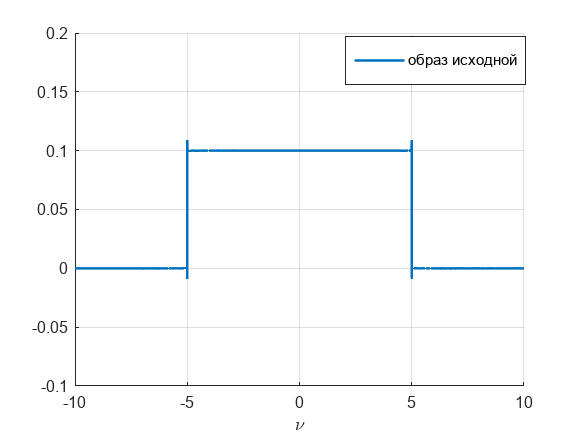

p1.LineWidth = 1.5;
grid on
xlabel("\nu")
xlim([-10 10])
ylim([-0.1 0.2])
legend('образ исходной')
hold off
legend("Position", [0.59783,0.80544,0.3095,0.111])

% saveas(f,'C:\LATEX\Fourier_analiz\Fourier_5\2_2Fu.png');

f1 = figure; %непрерывный и дискретный график
hold on
p2 = plot(v2, U_four); %восстановленная

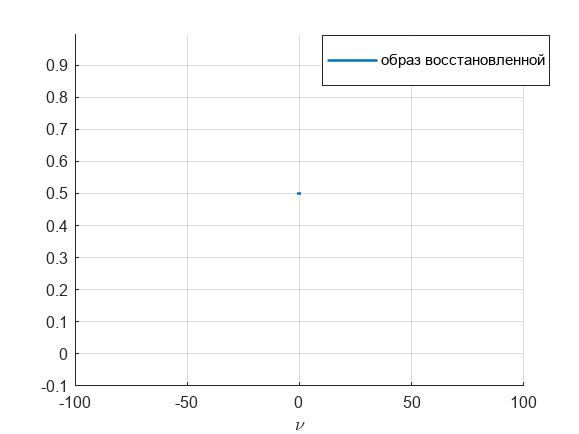

p2.LineWidth = 1.5;
grid on
xlabel("\nu")
xlim([-100 100])
ylim([-0.1 1])
legend('образ восстановленной')
hold off
legend("Position", [0.59783,0.80544,0.3095,0.111])

% saveas(f1,'C:\LATEX\Fourier_analiz\Fourier_5\2_2Fuu.png');

function y = fun(t)
    b = 10;
    y = sinc(b*t);
end